# ISONE hourly bid and demand data analysis

## Get selected date and hours from price analysis

selDate = '08/01/2019';
selHour = 20;

## Import ISONE hourly bid data

% Import ISONE hourly bid data in 2019 whole year
% Run this under the model_code directory or change the genFileDir manually
bidFileDir = "..\data\2019_DAM_BID_ISONE\";
bidFileName = "hbdayaheadenergyoffer_";
bidFileDate = datestr(selDate, 'yyyymmdd');
% bidDataStore = fileDatastore(bidFileDir + bidFileName, "ReadFcn", @importBidISONE, "UniformRead", true);
% bidAll = readall(bidDataStore);
hourlyBid = importBidISONE(bidFileDir + bidFileName + bidFileDate + ".csv");

## Import ISONE hourly demand data

% Import hourly generation data of generators in RGGI database in the 2019 whole year
% Run this under the model_code directory or change the genFileDir manually
demandFileDir = "..\data\2019_DEMAND_ISONE\";
demandFileName = "da_hourlydemand_2019*.csv";
demandDataStore = fileDatastore(demandFileDir + demandFileName, "ReadFcn", @importDemandISONE, "UniformRead", true);
demandAll = readall(demandDataStore);
clear demandDataStore;

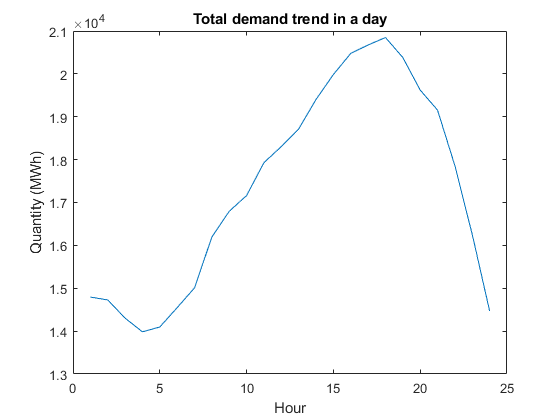

hourlyDemand = demandAll(demandAll.Date == selDate, :);
figure;
plot(hourlyDemand.DayAheadDemand);
title("Total demand trend in a day");
xlabel("Hour");
ylabel("Quantity (MWh)");
box on;

## Calculate aggregated supply function

### Construct stepwise aggregated supply function

% Obtain total demand at the selected hour
selHourDemand = hourlyDemand(hourlyDemand.Hour == selHour, :).DayAheadDemand;
% Obtain bids at the selected hour
allBids = hourlyBid(hourlyBid.Hour == selHour, :);
allBids = removevars(allBids, ["Date", "Hour", "MustTakeEnergy", "MaximumDailyEnergyAvailable", "EconomicMaximum", "EconomicMinimum", ...
    "ColdStartupPrice", "IntermediateStartupPrice", "HotStartupPrice", "NoLoadPrice"]);
allBids = movevars(allBids, "UnitStatus", "After", "AssetID");
allBids = movevars(allBids, "DateTime", "Before", "ParticipantID");
% remove unavailable units, left with economic and must-run units
availBids = allBids(allBids.UnitStatus ~= "UNAVAILABLE", :);

% Stack all bids together 
seg1 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment1Price", "Segment1MW"]));
seg2 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment2Price", "Segment2MW"]));
seg3 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment3Price", "Segment3MW"]));
seg4 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment4Price", "Segment4MW"]));
seg5 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment5Price", "Segment5MW"]));
seg6 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment6Price", "Segment6MW"]));
seg7 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment7Price", "Segment7MW"]));
seg8 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment8Price", "Segment8MW"]));
seg9 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment9Price", "Segment9MW"]));
seg10 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment10Price", "Segment10MW"]));
stackedBids = cell2table([seg1; seg2; seg3; seg4; seg5; seg6; seg7; seg8; seg9; seg10], ...
    "VariableNames", ["ParticipantID", "AssetID", "SegmentPrice", "SegmentMW"]);
% Remove NA bids
stackedBids = rmmissing(stackedBids);
% Sort bids by price from lowest to highest
stackedBids = sortrows(stackedBids, "SegmentPrice", "ascend");
% Calculate cumulative bid quantity
stackedBids.CumsumMW = cumsum(stackedBids.SegmentMW)

stackedBids = 797×5 table
    ParticipantID    AssetID    SegmentPrice    SegmentMW    CumsumMW
    _____________    _______    ____________    _________    ________

       124454         57942         -150           0.1          0.1  
       355376         32041         -150            24         24.1  
       384652         55290         -150             2         26.1  
       399648         42103         -150             8         34.1  
       399648         46072         -150             3         37.1  
       399648         77213         -150            13         50.1  
       399648         87105         -150            32         82.1  
       399648         97130         -150            30        112.1  
       412080         15908         -150            15        127.1  
       441991         98444      

### Plot aggregated supply function

stepBids = [stackedBids.CumsumMW, stackedBids.SegmentPrice];
stepNum = size(stepBids, 1);
stepBids4Plot = zeros(stepNum*2, 2);
for i = 1:stepNum-1
    stepBids4Plot(2*i, :) = stepBids(i, :);
    stepBids4Plot(2*i+1, 1) = stepBids(i, 1);
    stepBids4Plot(2*i+1, 2) = stepBids(i+1, 2);
end
stepBids4Plot(1, 2) = stepBids(1, 2);
stepBids4Plot(end, :) = stepBids(end, :);
aggSupplyCurve = stepBids4Plot;

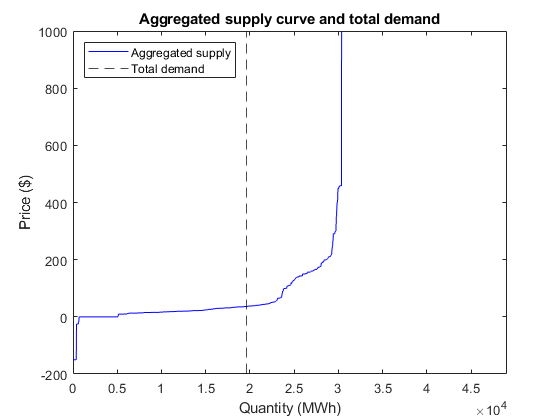

figure;
hold on;
plot(aggSupplyCurve(:, 1), aggSupplyCurve(:, 2), 'b');
xline(selHourDemand, 'k--');
hold off; box on;
legend(["Aggregated supply", "Total demand"], "Location", "northwest");
title("Aggregated supply curve and total demand");
xlabel("Quantity (MWh)");
ylabel("Price ($)");
xlim([0, selHourDemand*2.5]);

## Calculate supply curve of top market participants

### Find out awarded bids

stackedBids.AwardStatus = stackedBids.CumsumMW <= selHourDemand;
stackedBids.AwardStatus = categorical(stackedBids.AwardStatus);
stackedBids.AwardedMW = zeros(size(stackedBids, 1),1);
foundMarginal = 0;
for i=1:size(stackedBids, 1)
    if (stackedBids(i, :).AwardStatus == "true") && (foundMarginal == 0)
        stackedBids(i, :).AwardedMW = stackedBids(i, :).SegmentMW;
    elseif (stackedBids(i, :).AwardStatus == "false") && (foundMarginal == 0)
        foundMarginal = 1;
        stackedBids(i, :).AwardStatus = "marginal";
        stackedBids(i, :).AwardedMW = selHourDemand - stackedBids(i-1, :).CumsumMW;
    elseif (stackedBids(i, :).AwardStatus == "false") && (foundMarginal == 1)
        stackedBids(i, :).AwardedMW = 0;
    else
        stackedBids(i, :).AwardedMW = nan;
    end
end
stackedBids.AwardedCumsumMW = cumsum(stackedBids.AwardedMW)

stackedBids = 797×8 table
    ParticipantID    AssetID    SegmentPrice    SegmentMW    CumsumMW    AwardStatus    AwardedMW    AwardedCumsumMW
    _____________    _______    ____________    _________    ________    ___________    _________    _______________

       124454         57942         -150           0.1          0.1         true           0.1              0.1     
       355376         32041         -150            24         24.1         true            24             24.1     
       384652         55290         -150             2         26.1         true             2             26.1     
       399648         42103         -150             8         34.1         true             8             34.1     

### Calculate total awarded bids of each market participant

participantIDs = unique(availBids.ParticipantID);
partAwarded = zeros(size(participantIDs, 1), 1);
partUnawarded = zeros(size(participantIDs, 1), 1);
partTotBid = zeros(size(participantIDs, 1), 1);
for i = 1:size(participantIDs, 1)
    partBids = stackedBids(stackedBids.ParticipantID == participantIDs(i), :);
    partAwarded(i) = sum(partBids.AwardedMW);
    partTotBid(i) = sum(partBids.SegmentMW);
    partUnawarded(i) = partTotBid(i) - partAwarded(i);
end
% find out the market participants with largest awarded bid amount
partBidTable = table(participantIDs, partAwarded, partUnawarded, partTotBid);
partBidTable = sortrows(partBidTable, "partAwarded", "descend")

partBidTable = 83×4 table
    participantIDs    partAwarded    partUnawarded    partTotBid
    ______________    ___________    _____________    __________

        591975            2804             278            3082  
        401592            2114               0            2114  
        212494            1863              28            1891  
        206845          1564.6           964.5          2529.1  
        902793          1418.2          1056.5          2474.7  
        504170            1394             451            1845  
        872788             983              50            1033  
        328723             875            96.5           971.5  
        958512             844               4             848  
        595644             549               0             549  
        739738           475.3           502.4           

topParticipants = partBidTable(1:10, :).participantIDs;
topPartAwarded = partBidTable(1:10, :).partAwarded;

### Construct supply function of top market participants

topPartBidsTables = cell(size(topParticipants));
for i = 1:size(topParticipants, 1)
    % Obtain bids off one top participant
    partBids = availBids(availBids.ParticipantID == topParticipants(i), :);
    % Stack all bids together 
    seg1 = table2cell(partBids(:, ["ParticipantID", "AssetID", "Segment1Price", "Segment1MW"]));
    seg2 = table2cell(partBids(:, ["ParticipantID", "AssetID", "Segment2Price", "Segment2MW"]));
    seg3 = table2cell(partBids(:, ["ParticipantID", "AssetID", "Segment3Price", "Segment3MW"]));
    seg4 = table2cell(partBids(:, ["ParticipantID", "AssetID", "Segment4Price", "Segment4MW"]));
    seg5 = table2cell(partBids(:, ["ParticipantID", "AssetID", "Segment5Price", "Segment5MW"]));
    seg6 = table2cell(partBids(:, ["ParticipantID", "AssetID", "Segment6Price", "Segment6MW"]));
    seg7 = table2cell(partBids(:, ["ParticipantID", "AssetID", "Segment7Price", "Segment7MW"]));
    seg8 = table2cell(partBids(:, ["ParticipantID", "AssetID", "Segment8Price", "Segment8MW"]));
    seg9 = table2cell(partBids(:, ["ParticipantID", "AssetID", "Segment9Price", "Segment9MW"]));
    seg10 = table2cell(partBids(:, ["ParticipantID", "AssetID", "Segment10Price", "Segment10MW"]));
    partStackedBids = cell2table([seg1; seg2; seg3; seg4; seg5; seg6; seg7; seg8; seg9; seg10], ...
        "VariableNames", ["ParticipantID", "AssetID", "SegmentPrice", "SegmentMW"]);
    % Remove NA bids
    partStackedBids = rmmissing(partStackedBids);
    % Sort bids by price from lowest to highest
    partStackedBids = sortrows(partStackedBids, "SegmentPrice", "ascend");
    % Calculate cumulative bid quantity
    partStackedBids.CumsumMW = cumsum(partStackedBids.SegmentMW);
    topPartBidsTables{i} = partStackedBids;
end

### Plot supply curve of top market participants

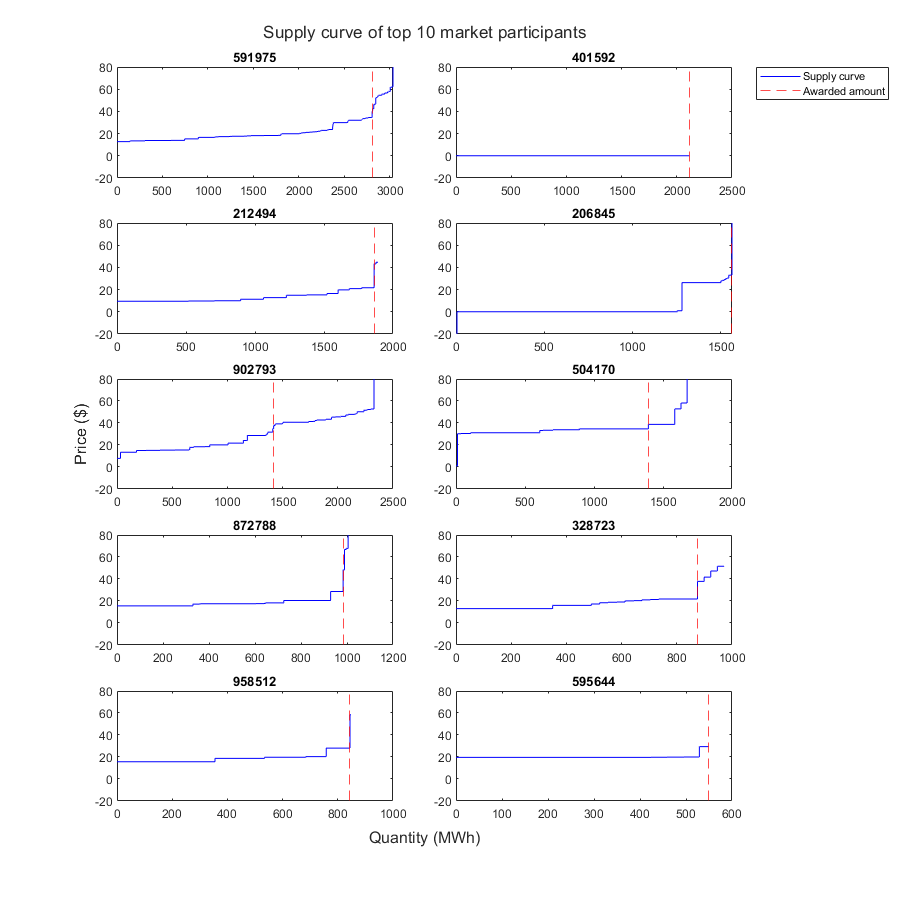

partSupplyCurves = cell(size(topParticipants));
t = tiledlayout(5,2,"TileSpacing","compact");
for i = 1:size(topParticipants, 1)
    % Construct step fuction for plot
    partStackedBids = topPartBidsTables{i};
    partiID = topParticipants(i);
    stepBids = [partStackedBids.CumsumMW, partStackedBids.SegmentPrice];
    stepNum = size(stepBids, 1);
    stepBids4Plot = zeros(stepNum*2, 2);
    for j = 1:stepNum-1
        stepBids4Plot(2*j, :) = stepBids(j, :);
        stepBids4Plot(2*j+1, 1) = stepBids(j, 1);
        stepBids4Plot(2*j+1, 2) = stepBids(j+1, 2);
    end
    stepBids4Plot(1, 2) = stepBids(1, 2);
    stepBids4Plot(end, :) = stepBids(end, :);
    partSupplyCurves{i} = stepBids4Plot;
    
    % Plot supply function
    nexttile;
    hold on;
    plot(partSupplyCurves{i}(:, 1), partSupplyCurves{i}(:, 2), 'b');
    xline(topPartAwarded(i), 'r--');
    hold off; box on;
    if i==2
        legend(["Supply curve", "Awarded amount"], "Location", "bestoutside");
    end    
    title(partiID);
    ylim([-20 80]);
end
xlabel(t, "Quantity (MWh)");
ylabel(t, "Price ($)");
title(t, "Supply curve of top 10 market participants");
set(gcf, "Position", [100, 100, 900, 900]);

## Plot aggregated supply curve excluding one top market participant

### Construct aggregated supply of other market participants

topOtherBidsTables = cell(size(topParticipants));
otherTotAwarded = zeros(size(topParticipants));
for i = 1:size(topParticipants, 1)
    otherBids = stackedBids(stackedBids.ParticipantID ~= topParticipants(i), :);
    otherBids.otherCumsumMW = cumsum(otherBids.SegmentMW);
    otherTotAwarded(i) = sum(otherBids.AwardedMW);
    topOtherBidsTables{i} = otherBids;
end

### Plot aggregated supply of other market participants

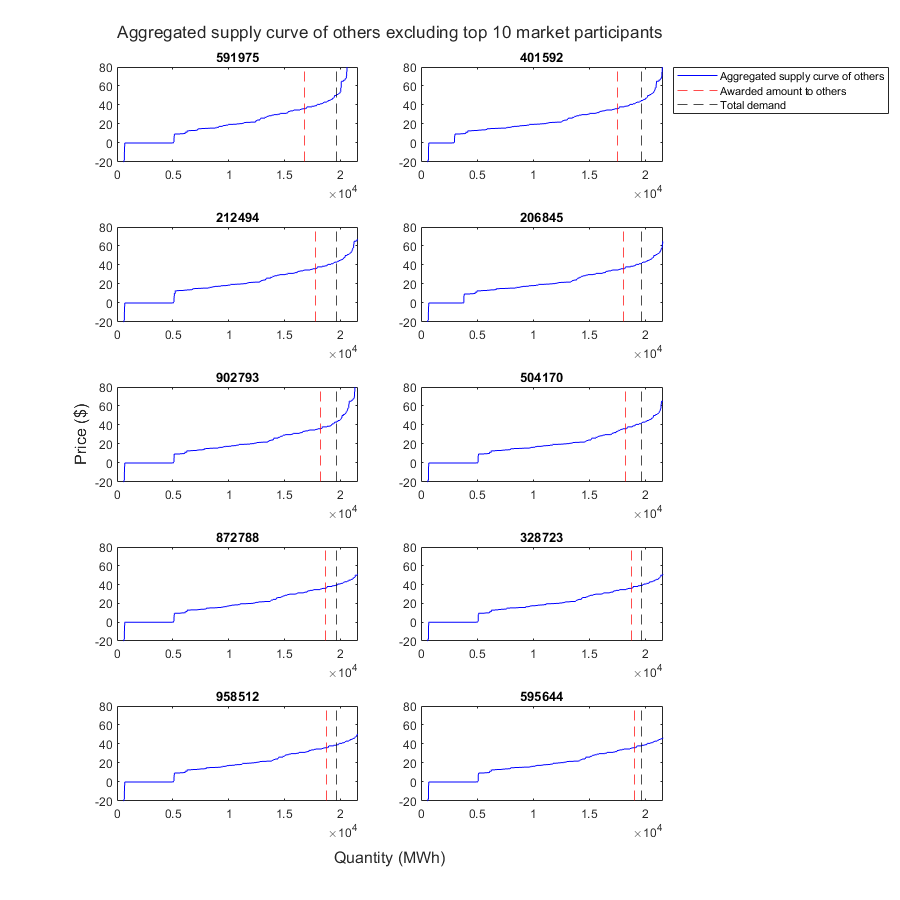

otherSupplyCurves = cell(size(topParticipants, 1), 1);
t = tiledlayout(5,2,"TileSpacing","compact");
for i = 1:size(topParticipants, 1)
    % Construct step fuction for plot
    otherStackedBids = topOtherBidsTables{i};
    partiID = topParticipants(i);
    stepBids = [otherStackedBids.otherCumsumMW, otherStackedBids.SegmentPrice];
    stepNum = size(stepBids, 1);
    stepBids4Plot = zeros(stepNum*2, 2);
    for j = 1:stepNum-1
        stepBids4Plot(2*j, :) = stepBids(j, :);
        stepBids4Plot(2*j+1, 1) = stepBids(j, 1);
        stepBids4Plot(2*j+1, 2) = stepBids(j+1, 2);
    end
    stepBids4Plot(1, 2) = stepBids(1, 2);
    stepBids4Plot(end, :) = stepBids(end, :);
    otherSupplyCurves{i} = stepBids4Plot;
    
    % Plot supply function exclude one top participant
    nexttile;
    hold on;
    plot(otherSupplyCurves{i}(:, 1), otherSupplyCurves{i}(:, 2), 'b');
    xline(otherTotAwarded(i), 'r--');
    xline(selHourDemand, 'k--');
    hold off; box on;
    if i==2
        legend(["Aggregated supply curve of others", "Awarded amount to others", "Total demand"], "Location", "bestoutside");
    end    
    title(partiID);
    axis([0 selHourDemand*1.1 -20 80]);
end
xlabel(t, "Quantity (MWh)");
ylabel(t, "Price ($)");
title(t, "Aggregated supply curve of others excluding top 10 market participants");

set(gcf, "Position", [100, 100, 900, 900]);

## Calculate and plot residuel demand function of top market participants

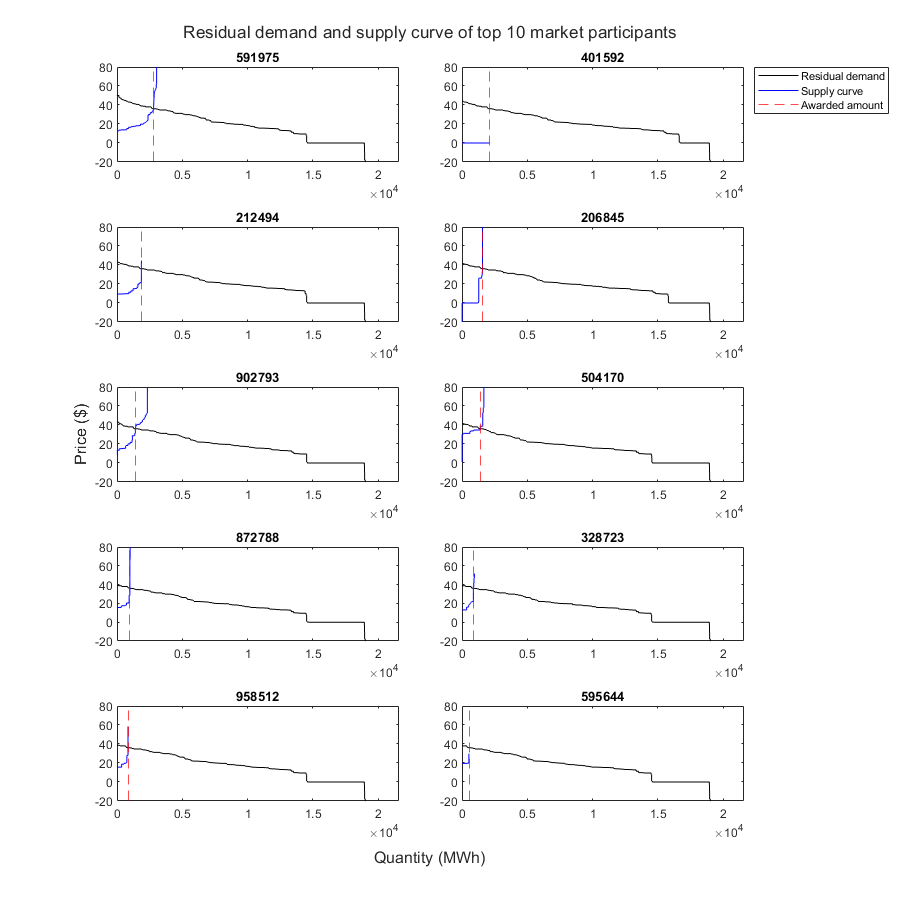

resiDemandCurves = cell(size(topParticipants));
t = tiledlayout(5,2,"TileSpacing","compact");
for i = 1:size(topParticipants, 1)
    partiID = topParticipants(i);
    % Construct step fuction for residual demand
    otherSupplyCurve = otherSupplyCurves{i};
    flipedSupplyCurve = flipud(otherSupplyCurve);
    resiDemandCurve = flipedSupplyCurve;
    resiDemandCurve(:, 1) = selHourDemand - flipedSupplyCurve(:, 1);
    resiDemandCurves{i} = resiDemandCurve;
    
    % Plot residual demand
    nexttile;
    hold on;
    plot(resiDemandCurves{i}(:, 1), resiDemandCurves{i}(:, 2), 'k');    
    % Plot supply curve
    plot(partSupplyCurves{i}(:, 1), partSupplyCurves{i}(:, 2), 'b');    
    % Plot awarded amount
    xline(topPartAwarded(i), 'r--');    
    hold off; box on;
    if i==2
        legend(["Residual demand", "Supply curve", "Awarded amount"], "Location", "bestoutside");
    end    
    title(partiID);
    axis([0 selHourDemand*1.1 -20 80]);
end
xlabel(t, "Quantity (MWh)");
ylabel(t, "Price ($)");
title(t, "Residual demand and supply curve of top 10 market participants");

set(gcf, "Position", [100, 100, 900, 900]);